run AircraftData.mlx

%Flight Conditions
V = 375; %kts 
h = 25000; %ft
DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT

[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
V=V*1.688;
M = V/SpeedSound;

%Airfoil Parameters
Cla = 2*pi;
Tmax = Vanguard.Wing.Airfoil.TMax;
LocMaxT = Vanguard.Wing.Airfoil.LocTMax;
PerLamFlow = Vanguard.Wing.Airfoil.PerLamFlow;
CLDMin = Vanguard.Wing.Airfoil.CldMin;

%Planform Parameters
S = Vanguard.Wing.S; %ft^2
b = Vanguard.Wing.b;
AR = Vanguard.Wing.AR;
TaperRatio = Vanguard.Wing.TaperRatio;
Q = 1.01;
SweepQuartC = Vanguard.Wing.QuarterChordSweep;

%Fuselage Parameters
Df = Vanguard.Fuselage.Diameter; %ft
LNose = Vanguard.Fuselage.NoseLength; %ft
LMid = Vanguard.Fuselage.CargoLength; %ft
LTail = Vanguard.Fuselage.TailLength; %ft
DBase = Vanguard.Fuselage.BaseDia; %ft
ABase = Vanguard.Fuselage.ABase;
UpsweepAngle = Vanguard.Fuselage.UpsweepAngle; %rad

%Vertical Tail Parameters NOTE: Half Wing
Sv = Vanguard.VerticalTail.S; %ft^2
ARv = Vanguard.VerticalTail.AR;
TaperRatiov = Vanguard.VerticalTail.TaperRatio;
bv = Vanguard.VerticalTail.b;
QVt = 1.05;
LocMaxTv = Vanguard.VerticalTail.LocTMax;
Tmaxv = Vanguard.VerticalTail.TMax;

%Horizontal Tail Parameters
Sh = Vanguard.HorizontalTail.S; %ft^2
ARh = Vanguard.HorizontalTail.AR;
TaperRatioh = Vanguard.HorizontalTail.TaperRatio;
bh = Vanguard.HorizontalTail.b;
QHt = 1.05;
LocMaxTh = Vanguard.HorizontalTail.LocTMax;
Tmaxh = Vanguard.HorizontalTail.TMax;

%Nacelle Parameters
LNacelle = 9.3;
DNacelle = 5.2;

%Blister Parameters
LBlister = 16;
DBlister = 3;

%Induced Drag Factor

Ne = 0; %Num of engines ON TOP of Wing
TaperFunc = 0.005*(1+1.5*(TaperRatio-0.6)^2);
K = (1+(0.142+TaperFunc*AR*(10*Tmax)^(0.33))/(cosd(SweepQuartC)^2)+(0.1*(3*Ne+1))/((4+AR)^0.8))*(1+0.12*M^6)/(pi*AR);
e = 1/(K*AR*pi);

%Total Zero-lift Drag

[CDoWing] = WingZeroLiftDrag(V,Q,TaperRatio,DynVisc,0,S,AR,b,h,LocMaxT,Df,PerLamFlow,Tmax);

V = 1.0685e+03

M = 1.0521

Cr = 16.6808

Cmac = 13.8454

Ymac = 25.2857

SweepMaxT = -1.6692

Re = 8.2601e+07

SweepMaxT = -1.6692

Cf = 0.0021

FF = 1.7248

Swet = 2.7001e+03

CDo = 0.0064


[CDoHt] = WingZeroLiftDrag(V,QHt,TaperRatioh,DynVisc,0,Sh,ARh,bh,h,LocMaxTh,0,PerLamFlow,Tmaxh);

V = 1.0685e+03

M = 1.0521

Cr = 16.6808

Cmac = 13.8454

Ymac = 9.5530

SweepMaxT = -1.6531

Re = 8.2601e+07

SweepMaxT = -1.6531

Cf = 0.0021

FF = 1.6583

Swet = 815.7600

CDo = 0.0076


CDoHt = CDoHt*Sh/S

CDoHt = 0.0019


[CDoVt] = WingZeroLiftDrag(V,QVt,TaperRatiov,DynVisc,0,Sv,ARv,bv,h,LocMaxTv,0,PerLamFlow,Tmaxv);

V = 1.0685e+03

M = 1.0521

Cr = 16.6808

Cmac = 13.8454

Ymac = 10.3920

SweepMaxT = -1.8842

Re = 8.2601e+07

SweepMaxT = -1.8842

Cf = 0.0021

FF = 1.6583

Swet = 1.2236e+03

CDo = 0.0076


CDoVt = CDoVt*Sv/S/2

CDoVt = 0.0014


[CDoFuse] = 0.0066 %ParaDragFuse(h,V,LMid,LNose,LTail,Df,DynVisc,S);

CDoFuse = 0.0066


[CDoNacelle] = 4*ParaDragNacelle(h,V,LNacelle,DNacelle,DynVisc,S);

Re = 3.2869e+07

Cf = 0.0023

FF = 1.1957

SWet = 151.9274

CDo = 3.9373e-04


[CDoBlisters] = ParaDragNacelle(h,V,LBlister,DBlister,DynVisc,S);

Re = 5.6549e+07

Cf = 0.0021

FF = 1.0656

SWet = 150.7964

CDo = 3.2008e-04


UpSweepDrag = 3.83*UpsweepAngle^2.5*pi*Df^2/4/S

UpSweepDrag = 0.0038


CDoCamber = e/(1-e)*K*CLDMin^2

CDoCamber = 0.0020


BaseDrag = (0.1+0.1222*M^8)*ABase/S

BaseDrag = 8.1852e-04


CDoTailProp = 0.00047

CDoTailProp = 4.7000e-04


CDoTotal = CDoWing+CDoHt+CDoVt+CDoFuse+CDoNacelle+CDoBlisters+UpSweepDrag+CDoCamber+BaseDrag+CDoTailProp  

CDoTotal = 0.0253

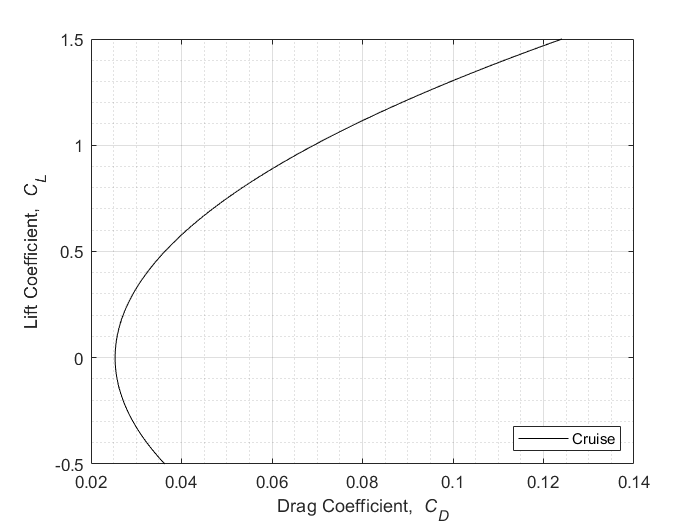





CL = -0.5:0.01:1.5 ;

LDMax = 0;

for x=1:201
    
   CD(x) = CDoTotal + K*CL(x)^2;
   
   if CL(x)/CD(x)>LDMax
       
       LDMax = CL(x)/CD(x);
       
   end
   
end

Line1 = [0];

% K2 = 1/(0.987*pi*AR)
% 
% LDMax2 = 0;
% 
% for x=1:201
%     
%    CD2(x) = CDoTotal2 + K2*CL(x)^2;
%    
%    if CL(x)/CD(x)>LDMax2
%        
%        LDMax2 = CL(x)/CD2(x)
%        
%    end
%    
% end

figure
plot (CD,CL,'black')
xlabel('Drag Coefficient, {\it C_{D}}')
ylabel('Lift Coefficient, {\it C_{L}}')
legend('Cruise','Location','southeast')
grid on
grid minor


% hold on
% 
% ax = gca;
% ax.XLim = [0 0.1152]
% %ax.XAxisLocation = 'origin';
% hold off

LDMax

LDMax = 14.9948


DynViscSL = 3.737*10^(-7);
Swf = 1100;

%%%%%%%%%%%%%%%%%%%%%
% Landing and Takeoff
%%%%%%%%%%%%%%%%%%%%%

[CDoWingSL] = WingZeroLiftDrag(100,Q,TaperRatio,DynViscSL,0,S,AR,b,0,LocMaxT,Df,PerLamFlow,Tmax);

V = 168.8000

M = 0.1513

Cr = 16.6808

Cmac = 13.8454

Ymac = 25.2857

SweepMaxT = -1.6692

Re = 2.5092e+07

SweepMaxT = -1.6692

Cf = 0.0024

FF = 1.2165

Swet = 2.7001e+03

CDo = 0.0050


[CDoHtSL] = WingZeroLiftDrag(100,QHt,TaperRatioh,DynViscSL,0,Sh,ARh,bh,0,LocMaxTh,0,PerLamFlow,Tmaxh);

V = 168.8000

M = 0.1513

Cr = 16.6808

Cmac = 13.8454

Ymac = 9.5530

SweepMaxT = -1.6531

Re = 2.5092e+07

SweepMaxT = -1.6531

Cf = 0.0024

FF = 1.1696

Swet = 815.7600

CDo = 0.0059


CDoHtSL = CDoHtSL*Sh/S;

[CDoVtSL] = WingZeroLiftDrag(100,QVt,TaperRatiov,DynViscSL,0,Sv,ARv,bv,0,LocMaxTv,0,PerLamFlow,Tmaxv);

V = 168.8000

M = 0.1513

Cr = 16.6808

Cmac = 13.8454

Ymac = 10.3920

SweepMaxT = -1.8842

Re = 2.5092e+07

SweepMaxT = -1.8842

Cf = 0.0024

FF = 1.1696

Swet = 1.2236e+03

CDo = 0.0059


CDoVtSL = CDoVtSL*Sv/S/2;

[CDoFuseSL] = ParaDragFuse(0,100,LMid,LNose,LTail,Df,DynViscSL,S);

Cf = 0.0021

FF = 1.2392

SWet = 4.2990e+03

CDo = 0.0071


[CDoNacelleSL] = 4*ParaDragNacelle(0,100,LNacelle,DNacelle,DynViscSL,S);

Re = 9.9849e+06

Cf = 0.0027

FF = 1.1957

SWet = 151.9274

CDo = 4.7319e-04


[CDoBlistersSL] = ParaDragNacelle(0,100,LBlister,DBlister,DynViscSL,S);

Re = 1.7178e+07

Cf = 0.0025

FF = 1.0656

SWet = 150.7964

CDo = 3.8330e-04


CDo_CleanSL = CDoWingSL + CDoHtSL + CDoVtSL + CDoFuseSL + UpSweepDrag + BaseDrag + CDoNacelleSL + CDoCamber;

k1 = 1.75;

k2Landing = 0.0375;

k2TO = 0.0125;

dCDoLanding = k1*k2Landing*Swf/S;

dCDoTO = k1*k2TO*Swf/S;

LDMaxL=0

LDMaxL = 0

LDMaxTO=0

LDMaxTO = 0


for x=1:201    
   CDLanding(x) = CDo_CleanSL+dCDoLanding + K*CL(x)^2;
   if CL(x)/CDLanding(x)>LDMaxL
       LDMaxL = CL(x)/CDLanding(x);
   end
   
   CDTO(x) = CDo_CleanSL+dCDoTO + K*CL(x)^2;
   if CL(x)/CDTO(x)>LDMaxTO
       LDMaxTO = CL(x)/CDTO(x);
   end
end

LDMax
LDMaxL

LDMaxL = 9.0888

LDMaxTO

LDMaxTO = 12.1713

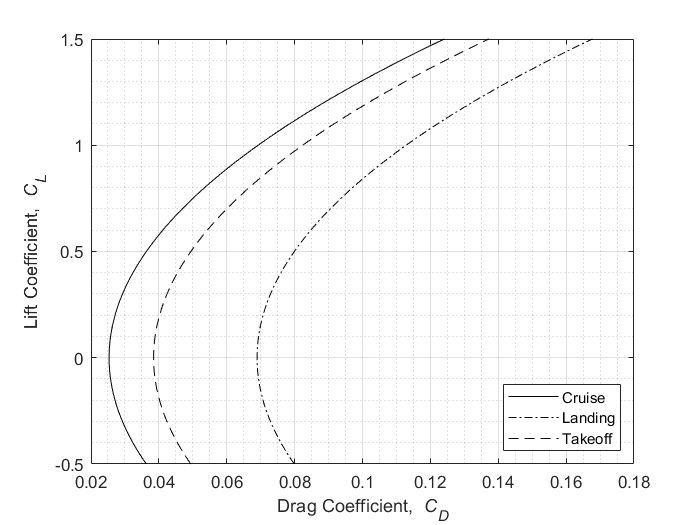


figure
plot (CD,CL,'black')
hold on
plot (CDLanding,CL,'black','LineStyle','-.')
plot (CDTO,CL,'black','LineStyle','--')
hold off
xlabel('Drag Coefficient, {\it C_{D}}')
ylabel('Lift Coefficient, {\it C_{L}}')

grid on
grid minor
legend('Cruise','Landing', 'Takeoff', 'Location','southeast')